## Comprobación numérica 

Dados


$$$V \sim N(\mu_v,\sigma_v^ 2)$$$


y:


$$\Phi/V=v \sim N\left(2 \pi L v,\frac{1}{2 L_0 \rho(v)^2 }\frac{1}{\frac{E_s}{N_0}}\right)$$


Donde L,y L0 son enteros constantes y $$\rho(v) =  \frac{sin(\pi L_0v)}{L_0 \, sin(\pi v)}$$

Se intenta comprobar numéricamente que $$\Phi$
$ se puede aproximar (de cara al BER que genera) para valores pequeños del sesgo y la varianza en V a:


$$\Phi \sim N\left(2 \pi L \mu_v, \left(\frac{1}{2 L_0  }\right)\frac{1}{\frac{E_s}{N_0}}+4\pi L^2\sigma_v^2\right)$$
 

mu_v = 2e-5;
sigma2_v = 1e-5;

L0 = 100;
L = 150;
EsN0 = 10;
N = 1e6;

mcrb_v = (3/(8* pi^2 * L0^3)) * (1/EsN0);
mcrb_phi = (1/(2*L0)) * (1/EsN0);

%Aprox
approx_distrib = normrnd(2*pi*L*mu_v,sqrt(mcrb_phi+4*pi^2 * L^2 *mcrb_v),[1,N]);

% Real
v = normrnd(mu_v,sqrt(mcrb_v),[1,N]);
ro = sin(pi*L0*v)./(L0*sin(pi*v));
real_distrib = normrnd(2*pi*L*v,sqrt(mcrb_phi./ ro.^2),[1,N]);

rad2deg(mean(real_distrib))

ans = 1.0791

rad2deg(mean(approx_distrib))

ans = 1.0834

rad2deg(sqrt(var(real_distrib)))

ans = 3.5692

rad2deg(sqrt(var(approx_distrib)))

ans = 3.5655

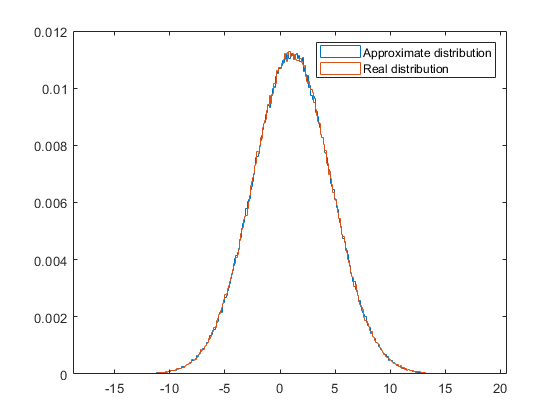

figure;
histogram(rad2deg(approx_distrib),'Normalization','probability', 'DisplayStyle', 'stairs');
hold on;
histogram(rad2deg(real_distrib),'Normalization','probability', 'DisplayStyle', 'stairs');
legend("Approximate distribution","Real distribution");